syms phi1 phi2 phi3 phi4 Tau F0 Tp v
K1 = 2.1875;
l1 = 0.08;
l2 = 0.08;
l3 = 0.08;
l4 = 0.08;
L_lib = [];
F_lib = [];
% for angle = 1 : 1 : 50
    phi1 = (180 - angle) *(pi/180)
    phi4 = angle *(pi/180)
    F0 = 696;
    Tp = 0;
    Xb = l1 * cos(phi1);
    Yb = l1 * sin(phi1);
    Xd = l4 * cos(phi4);
    Yd = l4 * sin(phi4);
    
    Lbd2 = (Xd - Xb)*(Xd - Xb) + (Yd - Yb)*(Xd - Xb);
    a = 2*l2* (Xd - Xb);
    b = 2*l2* (Yd - Yb);
    c = l2*l2 - l3*l3 + Lbd2;
    phi2 = phi4;
    phi3 = phi1;
    % phi2 = 2*atan2((b + sqrt(a*a + b*b - c*c)),(a + c));
    % phi3 = atan2(Yb-Yd+l2*sin(phi2),Xb-Xd+l2*cos(phi2));
    Xc = Xb + l2*cos(phi2);
    Yc = Yb + l2*sin(phi2);
    Xf = K1*Xc;
    Yf = K1*Yc;
    phi0 = atan(Yc/Xc);
    l0 = sqrt(Xf*Xf + Yf*Yf)
    
    J11 = -(K1*l1*sin(phi0 - phi3)*sin(phi1 - phi2))/sin(phi2 - phi3);
    J12 = -(K1*l1*cos(phi0 - phi3)*sin(phi1 - phi2))/(l0*sin(phi2 - phi3));
    J21 = -(K1*l4*sin(phi0 - phi2)*sin(phi3 - phi4))/sin(phi2 - phi3);
    J22 = -(K1*l4*cos(phi0 - phi2)*sin(phi3 - phi4))/(l0*sin(phi2 - phi3));
    
    J = [J11 J12;
         J21 J22];
    Tau = [-60;60];
    F_cartesian = pinv(J) * Tau;
    F_lib = [F_lib;F_cartesian(1)];
    L_lib = [L_lib;l0];
    % F = [F0 ; Tp];
    % T = J*F;
    % T1 = T(1,1)
    % T2 = T(2,1)
% end

phi1 = 3.1241

phi4 = 0.0175

l0 = 0.0061

F_cartesian =   342.9094
    0.0000


phi1 = 3.1067

phi4 = 0.0349

l0 = 0.0122

F_cartesian =   343.0661
    0.0000


phi1 = 3.0892

phi4 = 0.0524

l0 = 0.0183

F_cartesian =   343.3277
    0.0000


phi1 = 3.0718

phi4 = 0.0698

l0 = 0.0244

F_cartesian =   343.6944
   -0.0000


phi1 = 3.0543

phi4 = 0.0873

l0 = 0.0305

F_cartesian =   344.1668
    0.0000


phi1 = 3.0369

phi4 = 0.1047

l0 = 0.0366

F_cartesian =   344.7457
    0.0000


phi1 = 3.0194

phi4 = 0.1222

l0 = 0.0427

F_cartesian =   345.4319
         0


phi1 = 3.0020

phi4 = 0.1396

l0 = 0.0487

F_cartesian =   346.2266
    0.0000


phi1 = 2.9845

phi4 = 0.1571

l0 = 0.0548

F_cartesian =   347.1309
    0.0000


phi1 = 2.9671

phi4 = 0.1745

l0 = 0.0608

F_cartesian =   348.1463
   -0.0000


phi1 = 2.9496

phi4 = 0.1920

l0 = 0.0668

F_cartesian =   349.2743
    0.0000


phi1 = 2.9322

phi4 = 0.2094

l0 = 0.0728

F_cartesian =   350.5168
    0.0000


phi1 = 2.9147

phi4 = 0.2269

l0 = 0.0787

F_cartesian =   351.8757
    0.0000


phi1 = 2.8972

phi4 = 0.2443

l0 = 0.0847

F_cartesian =   353.3532
    0.0000


phi1 = 2.8798

phi4 = 0.2618

l0 = 0.0906

F_cartesian =   354.9518
    0.0000


phi1 = 2.8623

phi4 = 0.2793

l0 = 0.0965

F_cartesian =   356.6741
    0.0000


phi1 = 2.8449

phi4 = 0.2967

l0 = 0.1023

F_cartesian =  -358.5229
    0.0000


phi1 = 2.8274

phi4 = 0.3142

l0 = 0.1082

F_cartesian =   360.5013
    0.0000


phi1 = 2.8100

phi4 = 0.3316

l0 = 0.1139

F_cartesian =   362.6128
    0.0000


phi1 = 2.7925

phi4 = 0.3491

l0 = 0.1197

F_cartesian =   364.8610
   -0.0000


phi1 = 2.7751

phi4 = 0.3665

l0 = 0.1254

F_cartesian =   367.2497
   -0.0000


phi1 = 2.7576

phi4 = 0.3840

l0 = 0.1311

F_cartesian =   369.7833
   -0.0000


phi1 = 2.7402

phi4 = 0.4014

l0 = 0.1368

F_cartesian =   372.4664
    0.0000


phi1 = 2.7227

phi4 = 0.4189

l0 = 0.1424

F_cartesian =   375.3039
    0.0000


phi1 = 2.7053

phi4 = 0.4363

l0 = 0.1479

F_cartesian =   378.3010
    0.0000


phi1 = 2.6878

phi4 = 0.4538

l0 = 0.1534

F_cartesian =   381.4635
   -0.0000


phi1 = 2.6704

phi4 = 0.4712

l0 = 0.1589

F_cartesian =   384.7976
    0.0000


phi1 = 2.6529

phi4 = 0.4887

l0 = 0.1643

F_cartesian =   388.3097
    0.0000


phi1 = 2.6354

phi4 = 0.5061

l0 = 0.1697

F_cartesian =   392.0071
    0.0000


phi1 = 2.6180

phi4 = 0.5236

l0 = 0.1750

F_cartesian =   395.8973
    0.0000


phi1 = 2.6005

phi4 = 0.5411

l0 = 0.1803

F_cartesian =   399.9886
    0.0000


phi1 = 2.5831

phi4 = 0.5585

l0 = 0.1855

F_cartesian =   404.2897
    0.0000


phi1 = 2.5656

phi4 = 0.5760

l0 = 0.1906

F_cartesian =   408.8103
    0.0000


phi1 = 2.5482

phi4 = 0.5934

l0 = 0.1957

F_cartesian =   413.5604
    0.0000


phi1 = 2.5307

phi4 = 0.6109

l0 = 0.2008

F_cartesian =  -418.5513
   -0.0000


phi1 = 2.5133

phi4 = 0.6283

l0 = 0.2057

F_cartesian =   423.7947
   -0.0000


phi1 = 2.4958

phi4 = 0.6458

l0 = 0.2106

F_cartesian =   429.3037
    0.0000


phi1 = 2.4784

phi4 = 0.6632

l0 = 0.2155

F_cartesian =   435.0920
    0.0000


phi1 = 2.4609

phi4 = 0.6807

l0 = 0.2203

F_cartesian =   441.1747
    0.0000


phi1 = 2.4435

phi4 = 0.6981

l0 = 0.2250

F_cartesian =   447.5682
    0.0000


phi1 = 2.4260

phi4 = 0.7156

l0 = 0.2296

F_cartesian =   454.2902
    0.0000


phi1 = 2.4086

phi4 = 0.7330

l0 = 0.2342

F_cartesian =   461.3598
    0.0000


phi1 = 2.3911

phi4 = 0.7505

l0 = 0.2387

F_cartesian =   468.7980
    0.0000


phi1 = 2.3736

phi4 = 0.7679

l0 = 0.2431

F_cartesian =  -476.6275
   -0.0000


phi1 = 2.3562

phi4 = 0.7854

l0 = 0.2475

F_cartesian =   484.8732
    0.0000


phi1 = 2.3387

phi4 = 0.8029

l0 = 0.2518

F_cartesian =  -493.5622
   -0.0000


phi1 = 2.3213

phi4 = 0.8203

l0 = 0.2560

F_cartesian =   502.7243
    0.0000


phi1 = 2.3038

phi4 = 0.8378

l0 = 0.2601

F_cartesian =   512.3920
   -0.0000


phi1 = 2.2864

phi4 = 0.8552

l0 = 0.2641

F_cartesian =   522.6011
   -0.0000


phi1 = 2.2689

phi4 = 0.8727

l0 = 0.2681

F_cartesian =   533.3910
    0.0000


% p = polyfit(L_lib, F_lib, 3);


x_fit = linspace(min(L_lib), max(L_lib), 200);
y_fit = polyval(p, x_fit);

% 绘图
figure;
plot(x_fit, y_fit, 'b-', 'LineWidth', 1.5);
legend('原始点', '三次多项式拟合');

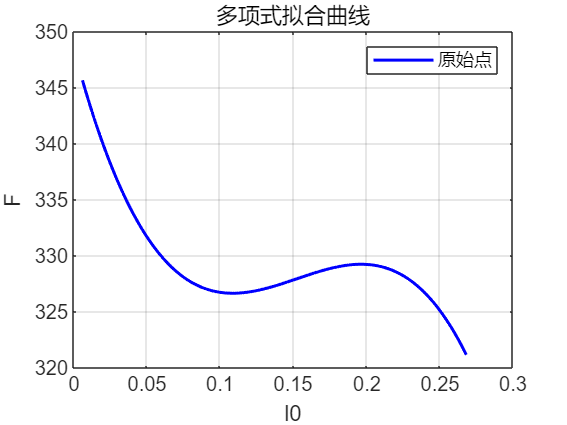

xlabel('l0'); ylabel('F'); grid on;
title('多项式拟合曲线');


p_int = polyint(p);                  % 对多项式积分，默认常数项为0
W = polyval(p_int, 0.3) - polyval(p_int, 0)

W = 98.4838

Wm = 25 * 0.3;
eqa = 0.5*25*v.^2 == W - Wm;
v=solve(eqa,v);
v=double(v)

v = 2×1
   -2.6979
    2.6979
